# ESEMPIO TEST DI DIAGNOSTICA "SOLLEVAMENTO A VUOTO"

### Carica in memoria il segnale nominale e il segnale acquisito

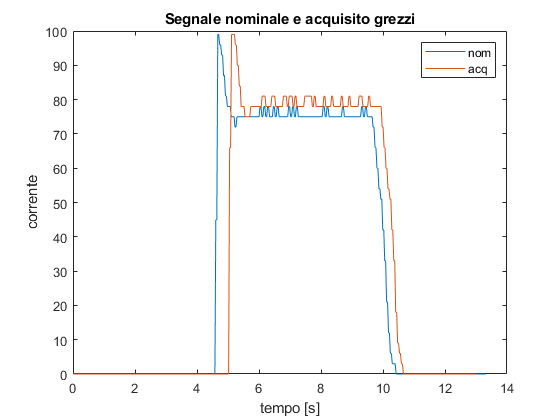

load('DATI_sv_0kg_5s.mat') % usato come segnale nominale in questo esempio
load('DATI_sv_22kg_5s.mat') % usato come segnale acquisito in questo esempio

% Plot dei dati grezzi acquisiti dall'inverter
figure
plot(DATI_sv_0kg_5s(:,1),DATI_sv_0kg_5s(:,2))
hold on
plot(DATI_sv_22kg_5s(:,1),DATI_sv_22kg_5s(:,2))
title('Segnale nominale e acquisito grezzi')
xlabel('tempo [s]')
ylabel('corrente')
legend('nom','acq')

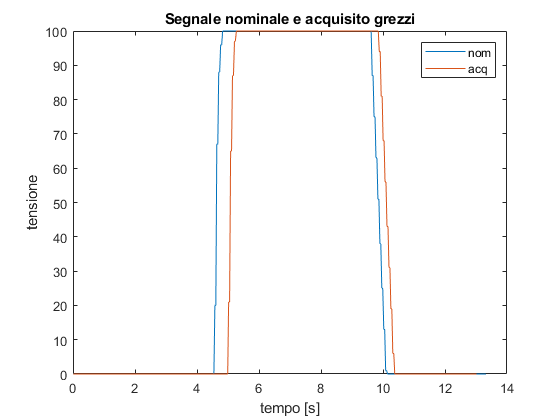


figure
plot(DATI_sv_0kg_5s(:,1),DATI_sv_0kg_5s(:,3))
hold on
plot(DATI_sv_22kg_5s(:,1),DATI_sv_22kg_5s(:,3))
title('Segnale nominale e acquisito grezzi')
xlabel('tempo [s]')
ylabel('tensione')
legend('nom','acq')

### Ricampionamento dei due segnali a frequenza fissa

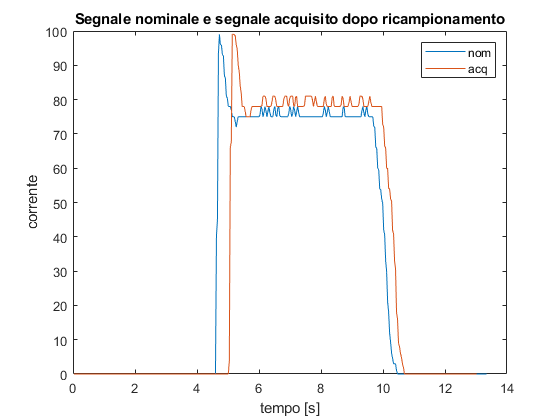

% Ricampiono il segnale nominale ad una frequenza di campionamento fissa 
% pari alla frequenza di acquisizione media e salvo il risultato in una
% struttura dati "segnale"
Sn = ricampionaSegnale(DATI_sv_0kg_5s(:,2), DATI_sv_0kg_5s(:,1),0);

% Ricampiono il segnale acquisito ad una frequenza di campionamento fissa
% uguale a quella usata per il segnale nominale e salvo il risultato in una
% struttura dati "segnale"
Sa = ricampionaSegnale(DATI_sv_22kg_5s(:,2), DATI_sv_22kg_5s(:,1),Sn.f);

% Plot dei due segnali ricampionati
figure
plotSegnale(Sn);
hold on
ylabel('corrente')
plotSegnale(Sa);
title('Segnale nominale e segnale acquisito dopo ricampionamento')
legend('nom','acq')

### Elaborazione del segnale nominale

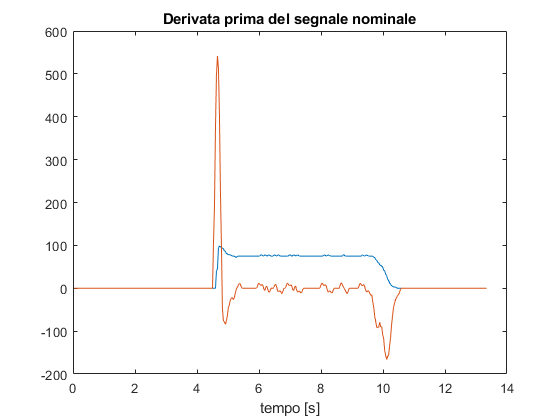

% Parametri per elaborazione del segnale nominale
n_d = 8; % [2,8], ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1], soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1], soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = 1; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

Sn_t = tagliaSegnaleUtile_sv(Sn,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
Sn_d = derivaSegnale(Sn,n_d);

figure
plotSegnale(Sn);
hold on;
plotSegnale(Sn_d);
title('Derivata prima del segnale nominale')

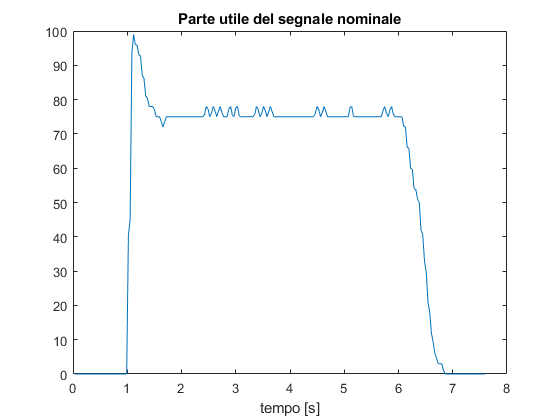


figure
plotSegnale(Sn_t);
title('Parte utile del segnale nominale')

## Elaborazione del segnale acquisito

n_d = 8; % ordine del filtro FIR per derivata prima
inizio_soglia = 0.7; % (0,1], soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1], soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = 1; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

S_t = tagliaSegnaleUtile_sv(Sa,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_d = derivaSegnale(Sa,n_d);

figure
plotSegnale(Sa);
hold on;
plotSegnale(S_d);
title('Derivata prima del segnale acquisito')

figure
plotSegnale(S_t);
title('Parte utile del segnale acquisito')

## Calcolo indice "Errore QuadraticoMedio"

%S_t.s = S_t.s*1.6;
%S_t = traslaSegnale(S_t,50,0,false);
%S_t = addNoise(S_t,0.00001,0.001);

figure
plotSegnale(Sn_t);
hold on
plotSegnale(S_t);

ind = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_t)